clearvars;

samples = 500

samples = 500

Ustawienia

Filename = "bruno.wav";
Dither_level = -70;
Bit_resolution = 9;

Wczytanie pliku i wygenerowanie szumu

[x, Fs] = audioread(Filename);

wav_size = size(x);
length = wav_size(1);

if wav_size(2) > 1
    x = x(:, 1);
end

white_noise = wgn(length, 1, Dither_level);
pink_noise = pinknoise(length)*0.01;

Zsumowanie szumów z nagraniem

x_2 = x + white_noise;
x_3 = x + pink_noise;

Zmiana poziomu kwantyzacji

x_quant = quant(x, Bit_resolution, true, 0, 0);
x_quant_2 = quant(x_2, Bit_resolution, true, 0, 0);
x_quant_3 = quant(x_3, Bit_resolution, true, 0, 0);


Wyznaczenie szumu kwantyzacji dla nagrania oryginalnego

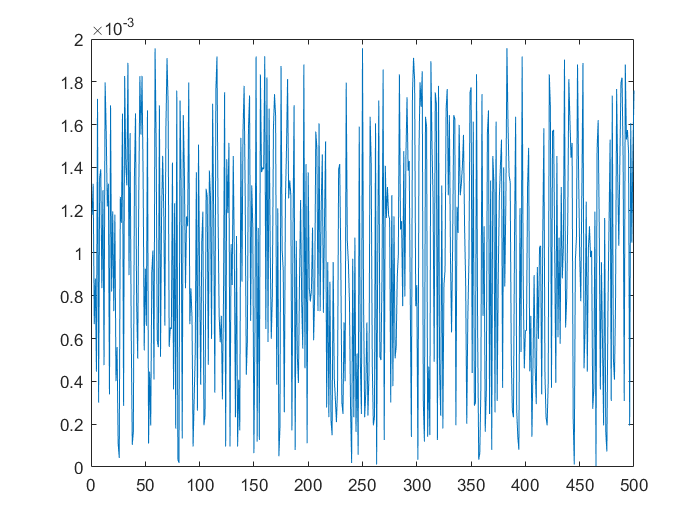

x_diff = abs(x - x_quant');
plot(1:samples, x_diff(1:samples))


"Suma szumu kwantyzacji"

ans = "Suma szumu kwantyzacji"

sum(x_diff)

ans = 215.8431


x_diff_2 = abs(x - x_quant_2');
plot(1:samples, x_diff(1:samples))


"Suma szumu kwantyzacji po ditheringu"

ans = "Suma szumu kwantyzacji po ditheringu"

sum(x_diff_2)

ans = 221.7027


x_diff_2 = abs(x - x_quant_3');
plot(1:samples, x_diff(1:samples))


"Suma szumu kwantyzacji po ditheringu"

ans = "Suma szumu kwantyzacji po ditheringu"

sum(x_diff_2)

ans = 222.4732

Wyznaczenie FFT

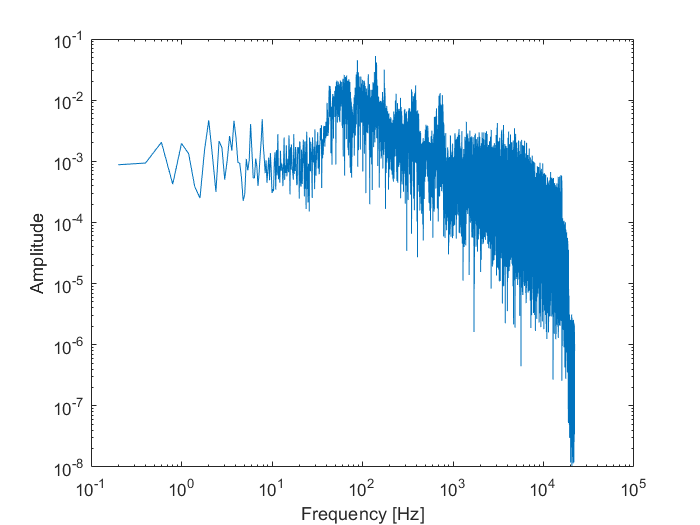



figure(1)
[y, P] = fft_plot(x, length, Fs);

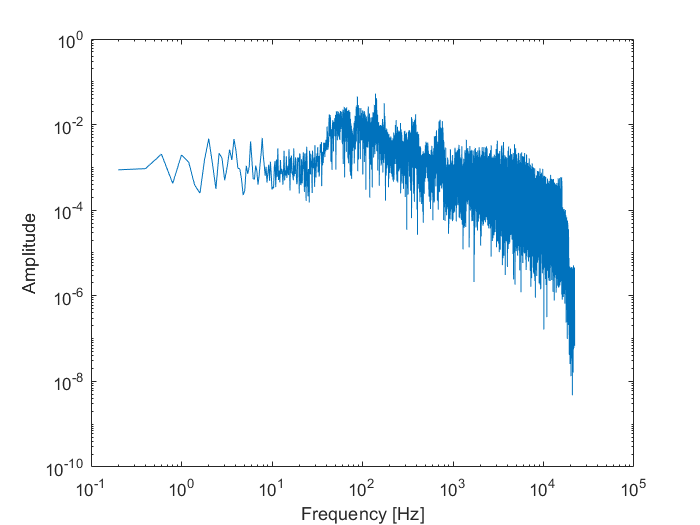

figure(2)
[y_2, P_2] = fft_plot(x_2, length, Fs);


figure(3)
[y_quant, P_quant] = fft_plot(x, length, Fs);

figure(4)
[y_quant_2, P_quant_2] = fft_plot(x_2, length, Fs);


% sound(x_quant, Fs, 8)
% pause(7);
% sound(x_2_quant, Fs, 8)


sum(P)

ans = 34.8858

sum(P_quant)

ans = 34.8858

sum(P_quant_2)

ans = 34.8954